% Generate the figures for Cleve's Corner.
% "Magic" Reconstruction: Compressed Sensing.
% MathWorks News and Notes, Fall, 2010.
% Use "L1 magic" by Justin Romberg.
% http://www.acm.caltech.edu/l1magic 
% f = signal = tone from "1" key on touch tone phone.
% b = random subsample.

Source:

Article: [https://www.mathworks.com/company/newsletters/articles/magic-reconstruction-compressed-sensing.html](https://www.mathworks.com/company/newsletters/articles/magic-reconstruction-compressed-sensing.html)

code: [https://www.mathworks.com/matlabcentral/fileexchange/28250-generate-figures-for-cleve-s-corner-on-compressed-sensing](https://www.mathworks.com/matlabcentral/fileexchange/28250-generate-figures-for-cleve-s-corner-on-compressed-sensing)

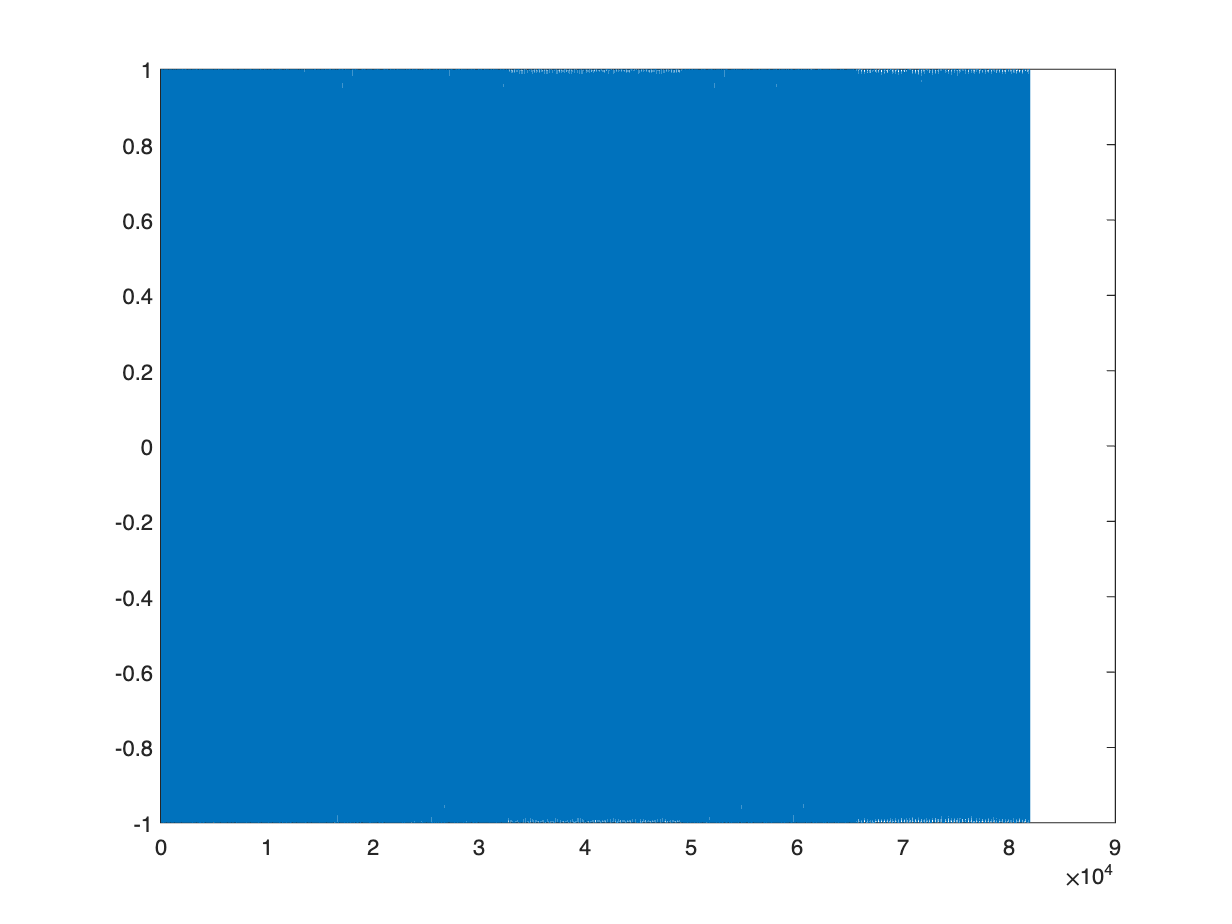

clear all; close all;

Fs=8192;
Ts=1/Fs;
t=[0:Ts:1];
F_A=440; %Frequency of note A is 440 Hz
F_E=659.26; %Frequency of note E
F_Fbar = 739.99; %Frequency of note F#
F_D= 587.33; %Frequency of note D

A=sin(2*pi*F_A*t);
E=sin(2*pi*F_E*t);
Fbar=sin(2*pi*F_Fbar*t);
D=sin(2*pi*F_D*t);

song = [A,A,E,E,Fbar,Fbar,E,E,D,D];
%figure();plot(song)

%sound(song,Fs);
audiowrite('Twinkle.wav',song,Fs);

cs_A = comp(A,t,10)';
cs_E = comp(E,t,10)';
cs_Fbar = comp(Fbar,t,10)';
cs_D = comp(D,t,10)';
cs_song = [cs_A,cs_A,cs_E,cs_E,cs_Fbar,cs_Fbar,cs_E,cs_E,cs_D,cs_D]

cs_song =     0.0130   -0.2487   -0.4091   -0.3427   -0.3891    0.0167    0.1916    0.2884    0.1746   -0.0048    0.1615    0.2228    0.2811    0.1383    0.0092   -0.3450   -0.3326   -0.1957   -0.2501    0.1285   -0.1409   -0.1478   -0.0921    0.1366    0.9700    0.4600    0.4396    0.3218    0.0649    0.2228    0.2620    0.1940    0.0178   -0.1821   -0.3360   -0.3667   -0.2197   -0.0730   -0.1639   -0.2892   -0.0714    0.0294   -0.0044    0.4406    0.4058    0.2702    0.2118   -0.0305    0.2143   -0.0190


sound(cs_song,Fs);
audiowrite('Twinkle_l1.wav',cs_song,Fs);

# Visualizing what happened:

Let's try note A + E+D first:



%AED= sin(2*pi*F_A*t)+ sin(2*pi*F_E*t) + sin(2*pi*F_D*t);
%AED = sin(2*pi*F_A*t);
AED = sin(2*pi*770*t) + sin(2*pi*1633*t);

audiowrite('B.wav',AED,Fs)

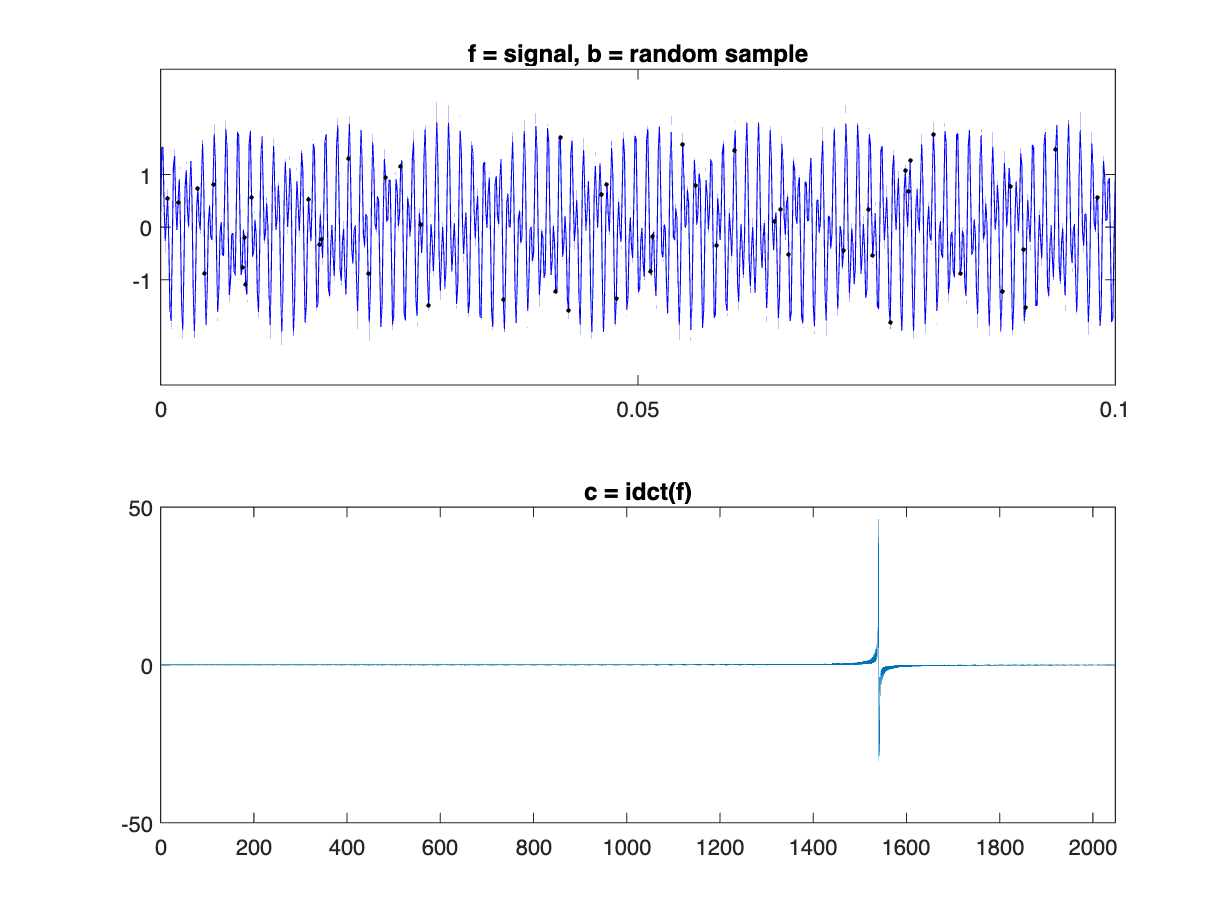


f = AED';
t = t';

n = length(f);
m = ceil(n/20); %20 percent sampling rate
k = randperm(n)';
k = sort(k(1:m));
b = f(k);


% Plot f and b.
% Plot idct(f) = inverse discrete cosine transform.
axf = [0 max(t)/10 -3 3];
axd = [0 n/4 -50 50];

figure();
subplot(2,1,1)
plot(t,f,'b-',t(k),b,'k.')
axis(axf);
set(gca,'xtick',0:0.05:1,'ytick',-1:1)
title('f = signal, b = random sample')
subplot(2,1,2)
plot(idct(f))
axis(axd);
set(gca,'xtick',0:200:Fs)
title('c = idct(f)')

drawnow




% A = rows of DCT matrix with indices of random sample.
A = zeros(m,n);
for i = 1:m
   ek = zeros(1,n);
   ek(k(i)) = 1;
   A(i,:) = idct(ek);
end
% y = l_2 solution to A*y = b.
y = pinv(A)*b;
% x = l_1 solution to A*x = b.
% Use "L1 magic".
x = l1eq_pd(y,A,A',b,5e-3,32);
% Plot x and dct(x).
% Good comparison with f.

audiowrite('B_l1.wav',dct(x),Fs);

audiowrite('B_l2.wav',dct(y),Fs);

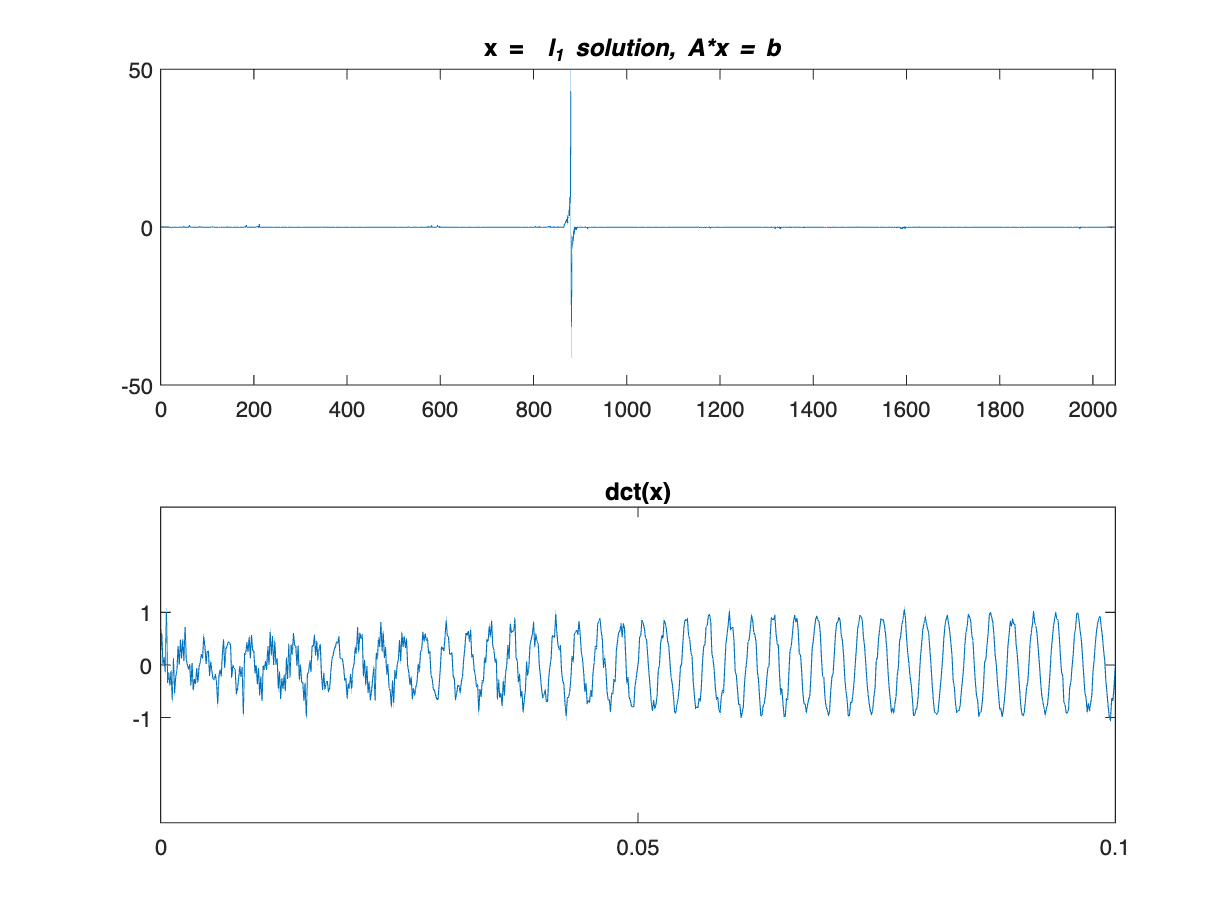



figure()
subplot(2,1,1)
plot(x)
axis(axd);
set(gca,'xtick',0:200:Fs)
title('x = {\it l}_1 solution, A*x = b ')
subplot(2,1,2)
plot(t,dct(x))
axis(axf);
set(gca,'xtick',0:.05:1,'ytick',-1:1)
title('dct(x)')

% Plot y and dct(y).
% Lousy comparison with f.

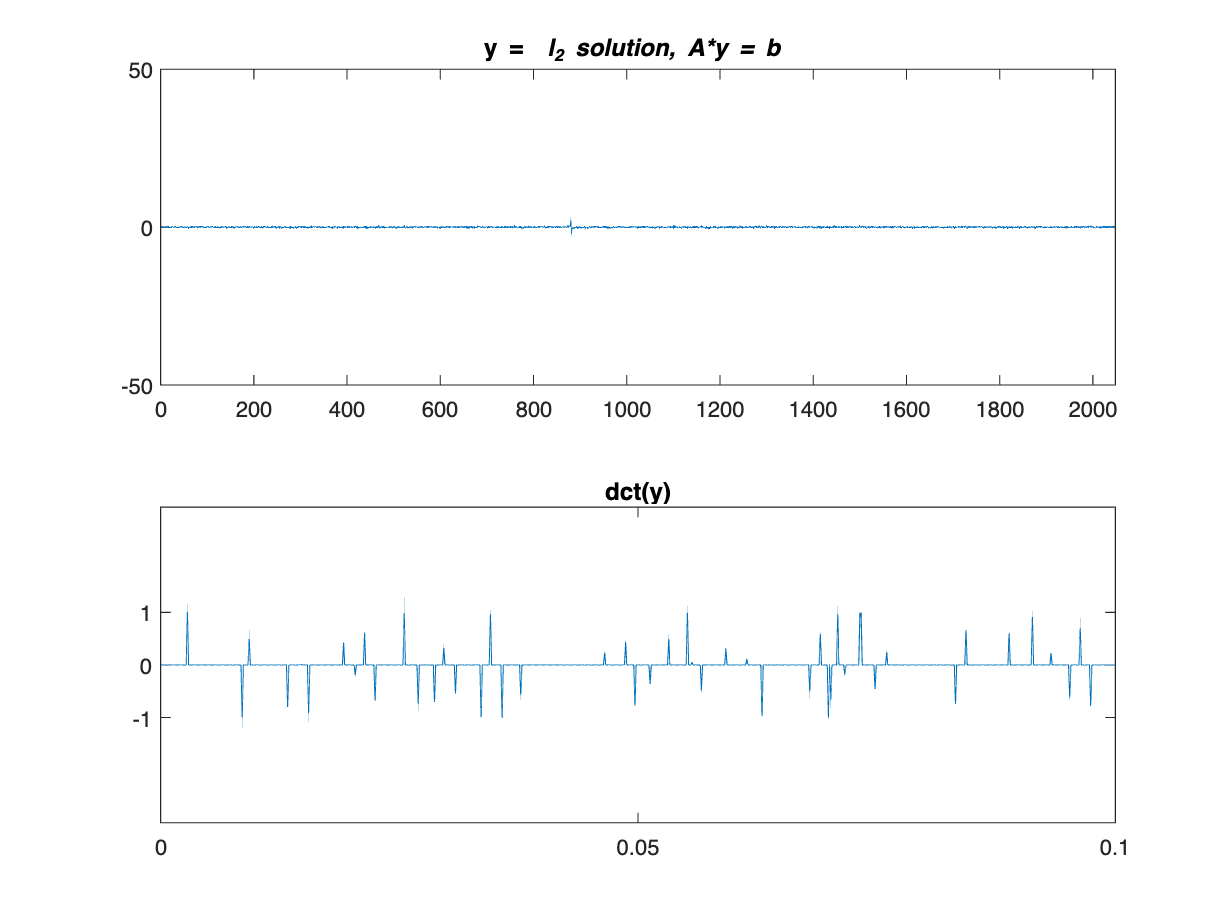




figure()
subplot(2,1,1)
plot(y)
axis(axd);
set(gca,'xtick',0:200:Fs)
title('y = {\it l}_2 solution, A*y = b ')
subplot(2,1,2)
plot(t,dct(y))
axis(axf);
set(gca,'xtick',0:.05:1,'ytick',-1:1)
title('dct(y)')

function f1 = comp(in,T,sr)
    f = in';
    t = T';
    
    n = length(f);
    m = ceil(n*sr/100); %sampling rate
    k = randperm(n)';
    k = sort(k(1:m));
    b = f(k);
    
    A = zeros(m,n);
    for i = 1:m
       ek = zeros(1,n);
       ek(k(i)) = 1;
       A(i,:) = idct(ek);
    end
    % y = l_2 solution to A*y = b.
    y = pinv(A)*b;
    % x = l_1 solution to A*x = b.
    % Use "L1 magic".
    x = l1eq_pd(y,A,A',b,5e-3,32);
    
    f1 = dct(x);
    f2 = dct(y);

end